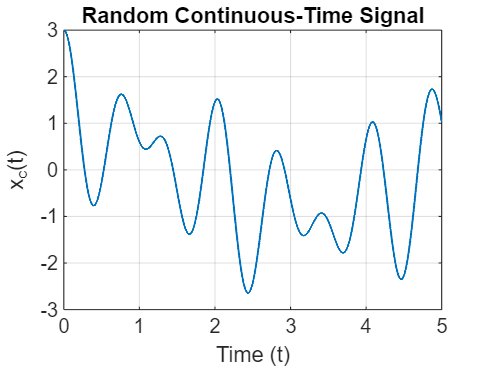

omega_N = 10;
I = 3;
T_max = 5;
omega_i = omega_N * rand(1,I); % Random frequency in the range (0, omega_n)
% Time vector
t = 0:1/1000:T_max;
% Generate random frequencies and the signal
xc_t = zeros(size(t)); % Initialize signal as zero
for i = 1:I
xc_t = xc_t + cos(omega_i(i) * t); % Accumulate cosine terms
end
% Plot the signal
figure;
plot(t, xc_t,LineWidth=1);
xlabel('Time (t)');
ylabel('x_c(t)');
title('Random Continuous-Time Signal');
grid on;

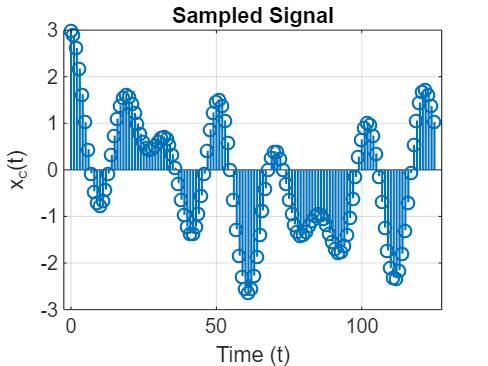

fs = 2.5*omega_N;
T = 1/fs;
n = 0:floor(T_max/T);
xn = zeros(size(n)); % Initialize signal as zero
for i = 1:I
xn = xn + cos(omega_i(i) * n * T); % Accumulate cosine terms
end
figure;
stem(n, xn,LineWidth=1);
xlabel('Time (t)');
ylabel('x_c(t)');
title('Sampled Signal');
grid on;

L = 3;
n1 = 0:floor(T_max/T)*L;
xe = zeros(size(n1)); % zero matrix of expanded signal of sampled signal x[n]
for i = 1:length(n1)
if mod(i-1, L) == 0
xe(i) = xn(((i-1)/L)+1); % Compute x( n / L) for n = 0, L, 2L, ...
else
xe(i) = 0; % Set x_e[n] to 0 for other values
end
end
xe

xe =     3.0000         0         0    2.9014         0         0    2.6164         0         0    2.1759         0         0    1.6274         0         0    1.0292         0         0    0.4437         0         0   -0.0697         0         0   -0.4619         0         0   -0.6989         0         0   -0.7654         0         0   -0.6661         0         0   -0.4243         0         0   -0.0780         0         0    0.3250         0         0    0.7336         0         0    1.0999         0


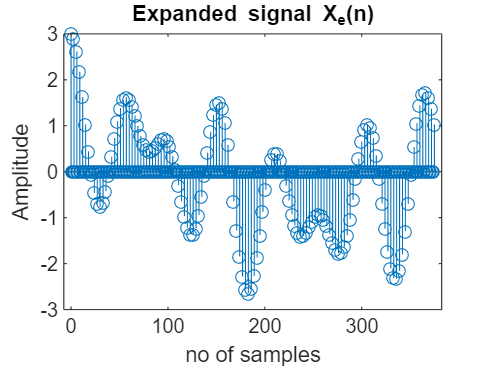

figure
stem(n1,xe)
xlabel('no of samples')
ylabel('Amplitude')
title('Expanded signal X_e(n)')

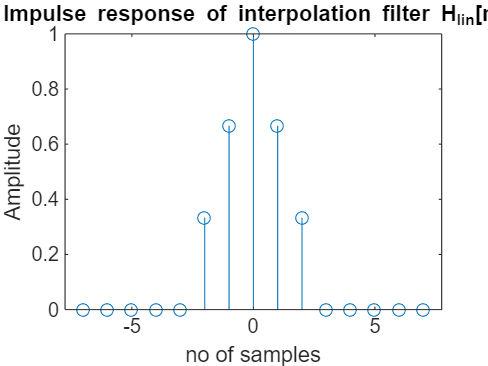

%impulse response of a linear interpolation signal
n2 = -7:1:7;
hlin = zeros(size(n2));
for i = 1:length(n2)
if (abs(n2(i))<L)
hlin(i) = 1 - (abs(n2(i))/L);
else
hlin(i) = 0;
end
end
figure
stem(n2,hlin)
xlabel('no of samples')
ylabel('Amplitude')
title('Impulse response of interpolation filter H_l_i_n[n]')

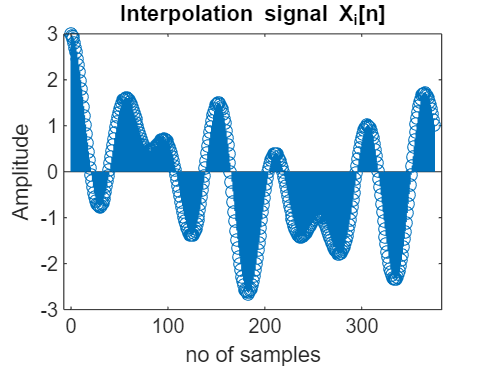

xi = conv(xe,hlin,'same'); % linear interpolation signal
figure
stem(n1,xi)
xlabel('no of samples')
ylabel('Amplitude')
title('Interpolation signal X_i[n]')

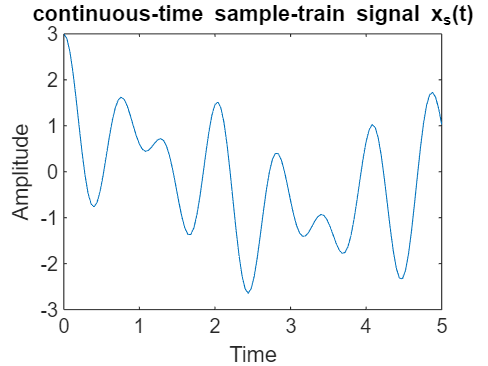

% continous time sample train signal
t1 = 0 : T/L : (length(xi)-1)*T/L;
xs = zeros(1,length(t1));
for n = 1:length(xi)
xs(n) = xi(n);
end
figure;
plot(t1, xs);
title('continuous-time sample-train signal x_s(t)');
xlabel('Time');
ylabel('Amplitude');

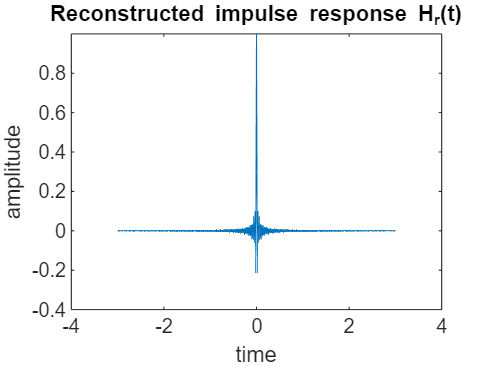

% reconstruction filter
t_filter = -3:1/100:3; % Time range for filter
h_rt = (sin((pi *L.*t_filter) / T)) ./ ((pi *L.*t_filter) / T); % impulse response of the reconstruction filter
h_rt(t_filter == 0) = 1; % Handling singularity at t = 0
figure
plot(t_filter,h_rt)
xlabel('time')
ylabel('amplitude')
title('Reconstructed impulse response H_r(t)')

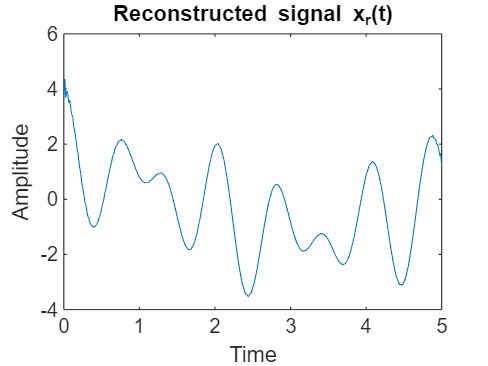

% reconstructed signal
xr = conv(xs,h_rt,'same');
figure;
plot(t1, xr);
title('Reconstructed signal x_r(t)');
xlabel('Time');
ylabel('Amplitude');